% 理解 meshgrid 的教学示例
clear; clc; close all;

% 定义 x 和 y 坐标范围
x = 1:4;
y = 2:5;

fprintf('原始向量:\n');

原始向量:


fprintf('x = '); disp(x);

x =      1     2     3     4



fprintf('y = '); disp(y);

y =      2     3     4     5




% 使用 meshgrid 创建网格坐标
[X, Y] = meshgrid(x, y);

fprintf('\nmeshgrid 生成的网格矩阵:\n');


meshgrid 生成的网格矩阵:


fprintf('X 矩阵 (每行都是 x 向量):\n'); disp(X);

X 矩阵 (每行都是 x 向量):
     1     2     3     4
     1     2     3     4
     1     2     3     4
     1     2     3     4



fprintf('Y 矩阵 (每列都是 y 向量):\n'); disp(Y);

Y 矩阵 (每列都是 y 向量):
     2     2     2     2
     3     3     3     3
     4     4     4     4
     5     5     5     5



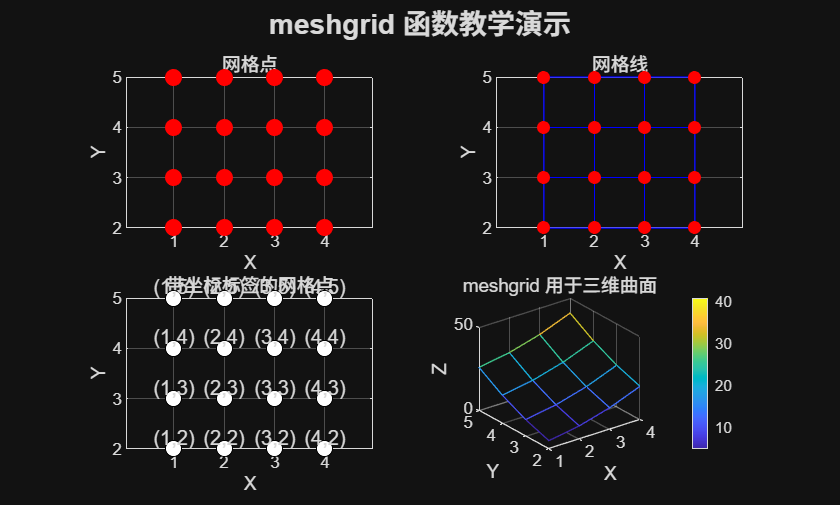


% 可视化网格点
figure;

% 方法1：绘制网格点
subplot(2,2,1);
plot(X, Y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
title('网格点');
xlabel('X'); ylabel('Y');
grid on;
axis equal;

% 方法2：绘制网格线
subplot(2,2,2);
plot(X, Y, 'b-', X', Y', 'b-'); % 绘制水平和垂直网格线
hold on;
plot(X, Y, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');
title('网格线');
xlabel('X'); ylabel('Y');
grid on;
axis equal;

% 方法3：显示坐标标签
subplot(2,2,3);
plot(X, Y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'w');
title('带坐标标签的网格点');
xlabel('X'); ylabel('Y');
grid on;
axis equal;

% 为每个点添加坐标标签
for i = 1:numel(X)
    text(X(i), Y(i), sprintf('(%.0f,%.0f)', X(i), Y(i)), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

% 方法4：演示 meshgrid 在三维绘图中的应用
subplot(2,2,4);
% 计算每个网格点的 Z 值（示例函数）
Z = X.^2 + Y.^2;

mesh(X, Y, Z);
title('meshgrid 用于三维曲面');
xlabel('X'); ylabel('Y'); zlabel('Z');
colorbar;

% 添加说明文本
sgtitle('meshgrid 函数教学演示', 'FontSize', 14, 'FontWeight', 'bold');


fprintf('\nmeshgrid 的作用:\n');


meshgrid 的作用:


fprintf('1. 将两个一维向量转换为二维网格坐标\n');

1. 将两个一维向量转换为二维网格坐标


fprintf('2. X 矩阵包含所有点的 x 坐标\n');

2. X 矩阵包含所有点的 x 坐标


fprintf('3. Y 矩阵包含所有点的 y 坐标\n');

3. Y 矩阵包含所有点的 y 坐标


fprintf('4. 常用于三维绘图和网格计算\n');

4. 常用于三维绘图和网格计算


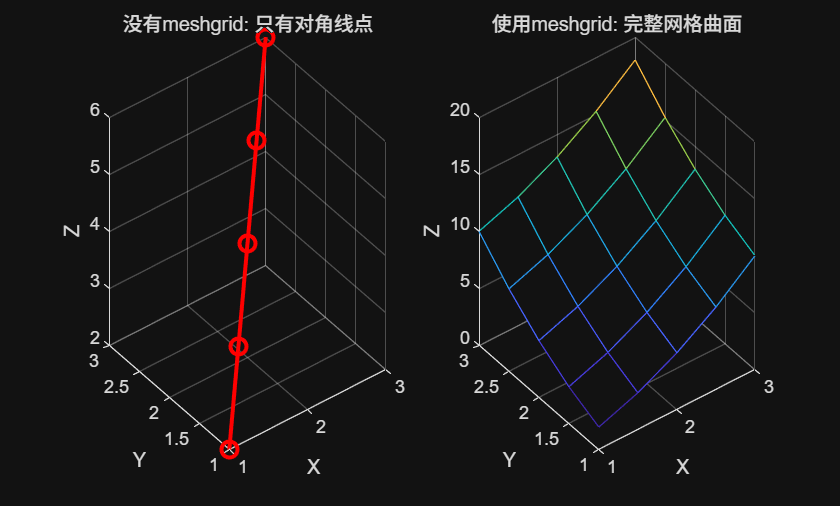

% 对比演示
x = 1:0.5:3;
y = 1:0.5:3;

figure;

% 子图1：没有meshgrid的情况
subplot(1,2,1);
z_no_mesh = x + y;
plot3(x, y, z_no_mesh, 'ro-', 'LineWidth', 2, 'MarkerSize', 8);
title('没有meshgrid: 只有对角线点');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on;

% 子图2：使用meshgrid的情况
subplot(1,2,2);
[X, Y] = meshgrid(x, y);
Z = X.^2 + Y.^2;
mesh(X, Y, Z);
title('使用meshgrid: 完整网格曲面');
xlabel('X'); ylabel('Y'); zlabel('Z');

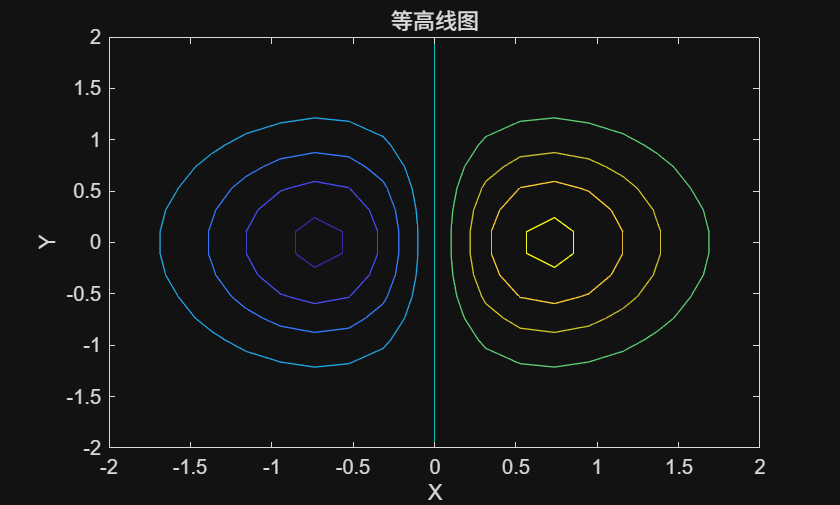

x = linspace(-2, 2, 20);
y = linspace(-2, 2, 20);
[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);

figure;
contour(X, Y, Z);
title('等高线图');
xlabel('X'); ylabel('Y');

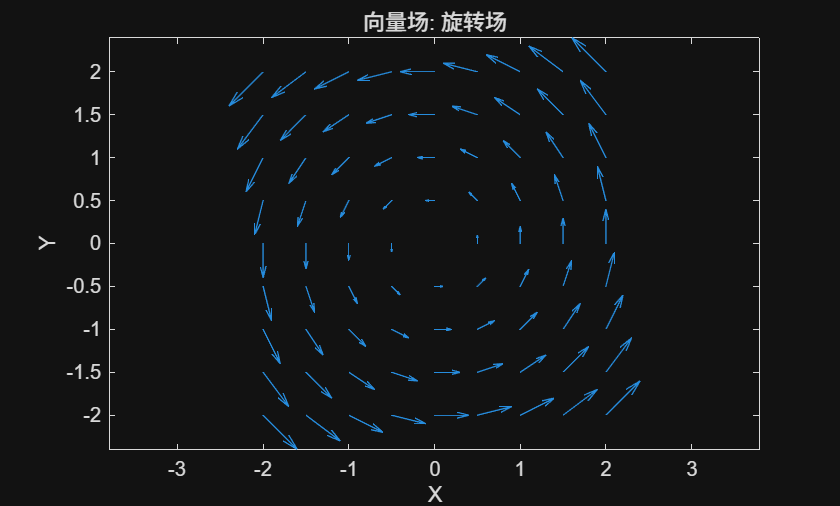

x = -2:0.5:2;
y = -2:0.5:2;
[X, Y] = meshgrid(x, y);

% 定义向量场
U = -Y;  % x方向分量
V = X;   % y方向分量

figure;
quiver(X, Y, U, V);
title('向量场: 旋转场');
xlabel('X'); ylabel('Y');
axis equal;

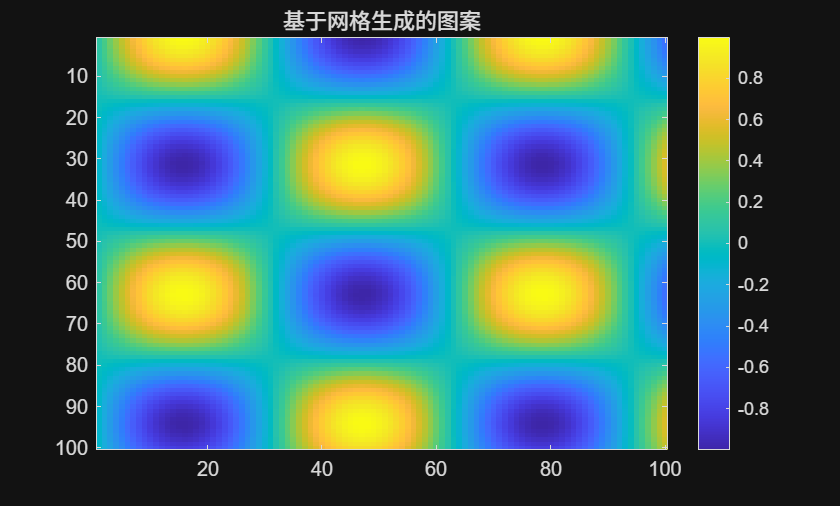

% 创建坐标网格来进行图像变换
[rows, cols] = deal(100);
[X, Y] = meshgrid(1:cols, 1:rows);

% 创建正弦波图案
Z = sin(0.1*X) .* cos(0.1*Y);

figure;
imagesc(Z);
colorbar;
title('基于网格生成的图案');

% 手动演示所有组合
x = [1 2 3];
y = [4 5 6];

fprintf('所有可能的 (x,y) 组合:\n');

所有可能的 (x,y) 组合:


for i = 1:length(x)
    for j = 1:length(y)
        fprintf('(%d, %d) ', x(i), y(j));
    end
    fprintf('\n');
end

(1, 4) (1, 5) (1, 6) (2, 4) (2, 5) (2, 6) (3, 4) (3, 5) (3, 6) 


% 这正好对应 meshgrid 的输出
[X, Y] = meshgrid(x, y);
fprintf('\nmeshgrid 的 X 矩阵:\n'); disp(X);


meshgrid 的 X 矩阵:
     1     2     3
     1     2     3
     1     2     3



fprintf('meshgrid 的 Y 矩阵:\n'); disp(Y);

meshgrid 的 Y 矩阵:
     4     4     4
     5     5     5
     6     6     6



% 演示有和没有 meshgrid 的区别
x = 1:3;
y = 1:3;

% 方法1：没有 meshgrid（只能处理向量）
z_no_mesh = x + y;  % 这实际上是 [1+1, 2+2, 3+3] = [2,4,6]

% 方法2：使用 meshgrid（可以处理整个网格）
[X, Y] = meshgrid(x, y);
z_with_mesh = X + Y;  % 这是完整的加法表

fprintf('没有 meshgrid:\n'); disp(z_no_mesh);

没有 meshgrid:
     2     4     6



fprintf('使用 meshgrid:\n'); disp(z_with_mesh);

使用 meshgrid:
     2     3     4
     3     4     5
     4     5     6

